定位于 KT2008.hmod，在 MATLAB 中 调用 **hans** 编译脚本文件。

hans KT2008

Parsing...
Symbolic parser failed. Switching to AD parser...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'sigma'  'alpha'  'nu'  'delta'  'xi_max'  'a'  'w'  'z'  'd'}
                var_shock: 'e'
                var_state: 'k'
              var_pre_vfi: {1×0 cell}
               var_policy: {'ka'  'kc'}
                  var_aux: {'p'  'nd'  'kp'  'y'  'c'}
                  var_agg: 'C'
            var_agg_shock: 'z'
           var_agg_params: {'chi'  'delta'  'sigma'  'beta'}
           var_agg_assign: {'d'  'w'}
    var_agg_in_ind_params: {'d'  'w'  'z'}
            var_ind_in_eq: {'y'  'nd'  'kp'  'k'}

我们首先求解校准模块。

tic;
cali_rslt = solve_cali;

Evaluating at var_agg: 0.4135, 2.32531, 
VFI converged (metric_v) 9.85215e-09, (metric_pol) 4.29862e-07 in 390 iterations
Range of k: 0, 3.68
Equilbirium residual: 0.000197203, -0.000149756, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   6.131594e-08   2.476205e-04
Evaluating at var_agg: 0.4136, 2.32531, 
VFI converged (metric_v) 9.64107e-09, (metric_pol) 2.48728e-07 in 227 iterations
Range of k: 0, 3.68
Equilbirium residual: 0.000959078, -0.000766295, 
Evaluating at var_agg: 0.4135, 2.32554, 
VFI converged (metric_v) 9.86429e-09, (metric_pol) 3.76106e-07 in 213 iterations
Range of k: 0, 3.68
Equilbirium residual: 0.000470949, -0.000404774, 
Evaluating at var_agg: 0.413464, 2.32538, 
VFI converged (metric_v) 9.81415e-09, (metric_pol) 7.01103e-08 in 216 iterations
Range of k: 0, 3.68
Equilbirium residual: 3.96032e-08, -1.34074e-09, 

             1              1   

toc;

Elapsed time is 1.464644 seconds.


cali_rslt.var_agg

ans = struct with fields:
      C: 0.4135
    chi: 2.3254
      z: 0
      w: 0.9615

我们随后通过传递校准后的参数求解稳态。

ss_rslt = solve_ss(cali_rslt);

Evaluating at var_agg: 0.413464, 
VFI result reused
Range of k: 0, 3.68
Equilbirium residual: 3.97218e-08, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   1.577820e-15   3.972178e-08
Evaluating at var_agg: 0.413464, 
VFI result reused
Range of k: 0, 3.68
Equilbirium residual: 3.97218e-08, 


让我们检查求解出的稳态总体变量。

ss_rslt.var_agg

ans = struct with fields:
    C: 0.4135
    z: 0
    d: 0.9610
    w: 0.9615
    N: 0.3333

让我们检查策略函数。承担调整成本的概率：

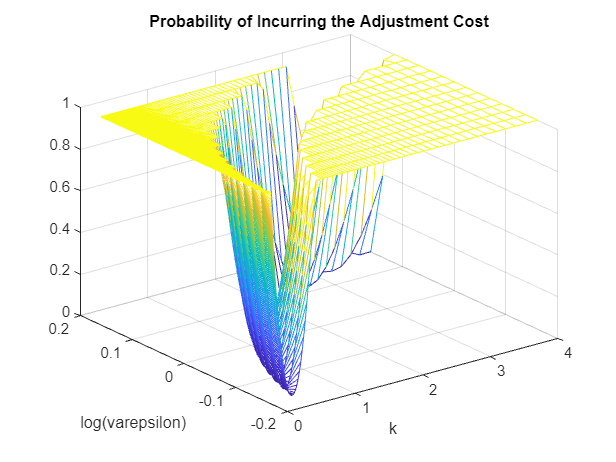

mesh(ss_rslt.vfi_rslt.var_state.k, ss_rslt.vfi_rslt.var_shock.e, ss_rslt.vfi_rslt.var_aux.p);
ylabel('log(varepsilon)');
xlabel('k');
title('Probability of Incurring the Adjustment Cost')

如上所示，投资决策呈现出 (S, s) 规则：当资本水平与预期水平相比过低或过高时，就会产生调整成本。

平稳分布：

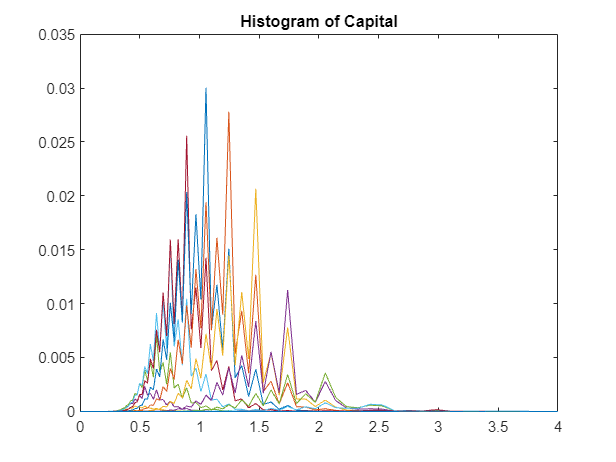

plot(ss_rslt.vfi_rslt.var_state.k,ss_rslt.dist); title('Histogram of Capital');

注意，直方图的锯齿状形状是一个特征。可以通过在 Winberry (2018) 求解稳态的代码中增加资本格点数量来复现这样的模式。

我们接下来生成总体生产率冲击的时间序列。

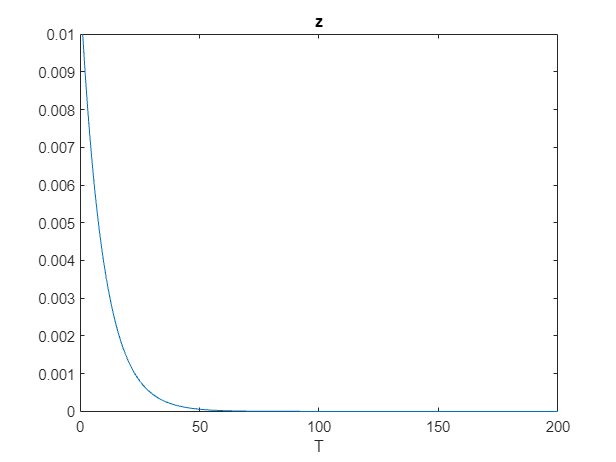

rho_z = 0.9;
size_z_shock = 0.01;
T = 200;
z_t = size_z_shock*rho_z.^[0:T-1];
plot(z_t); title('z'); xlabel('T')

我们将总体冲击传入模型并且求解转移路径。

注意，solve_trans_nonlinear 包含三个输入参数，第一个是起始稳态，第二个是最终稳态。

options = struct;
options.z_t = z_t;
tic;
trans_rslt = solve_trans_nonlinear(ss_rslt,ss_rslt,options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   3.386038e-07   5.818968e-04

             1              1              2   2.281655e-09   4.776667e-05   5.418998e-05   1.000000e+00        Broyden


toc;

Elapsed time is 10.657985 seconds.


让我们检查转移路径。

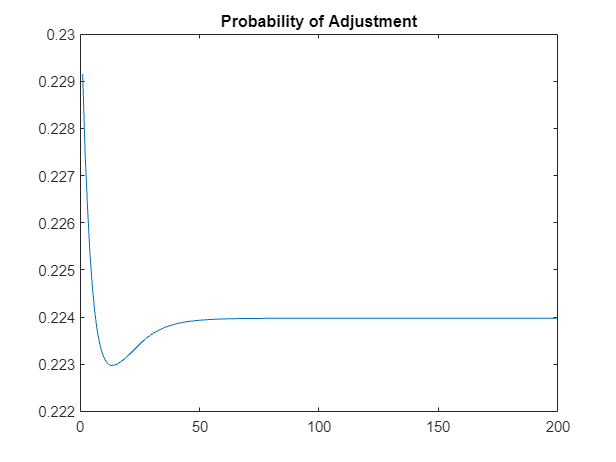

plot(trans_rslt.var_agg_t.p); title('Probability of Adjustment');

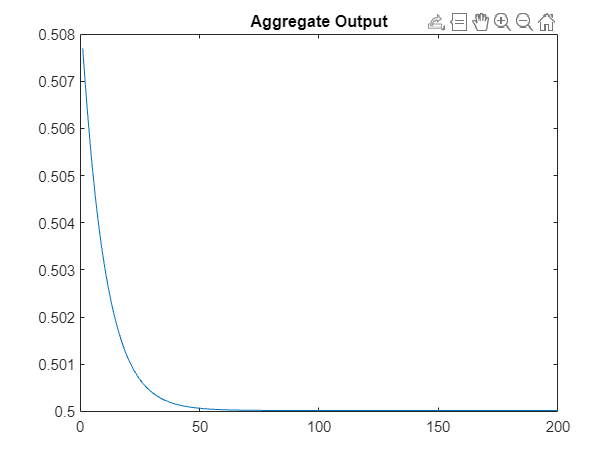

plot(trans_rslt.var_agg_t.y); title('Aggregate Output');

如上所示，在一个正向的生产率冲击发生后，承担固定调整成本的概率上升，这表明调整投资的重要份额处于广度边际上。

非凸调整成本能够生成总体非线性吗？

让我们提高冲击的规模，再次求解转移路径。

options.z_t = 10*z_t;
trans_large_shock = solve_trans_nonlinear(ss_rslt,ss_rslt,options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   3.372703e-03   5.807498e-02

             1              1              2   1.824057e-04   1.350577e-02   5.670312e-03   1.000000e+00        Broyden

             2              1              3   3.383330e-06   1.839383e-03   4.916697e-04   1.000000e+00        Broyden

             3              1              4   9.411725e-08   3.067854e-04   2.803021e-05   1.000000e+00        Broyden

             4              1              5   1.220428e-10   1.104730e-05   3.834561e-06   1.000000e+00        Broyden


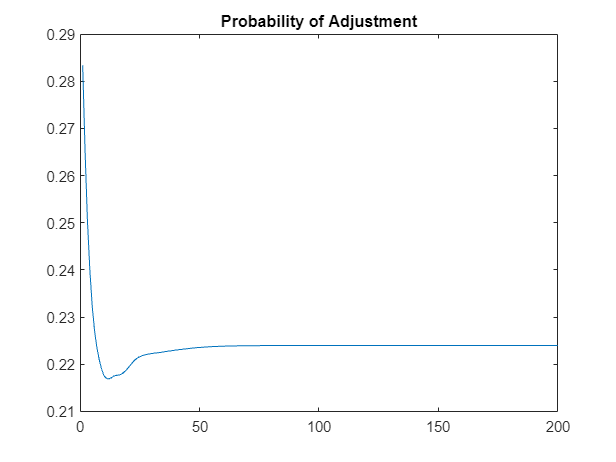

plot(trans_large_shock.var_agg_t.p); title('Probability of Adjustment');

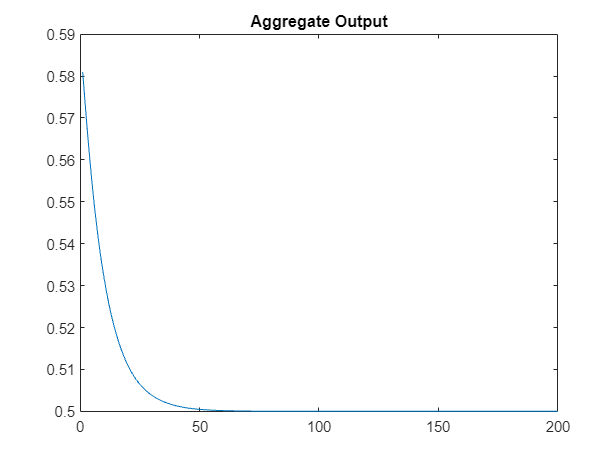

plot(trans_large_shock.var_agg_t.y); title('Aggregate Output');

如图所示，当冲击规模增加10倍时，内生变量的反应也会以大致相同的因子增加。

这表明尽管存在微观层面上的非凸调整成本，但模型并未呈现出总体非线性特征，这与 Khan & Thomas（2008）的研究结果一致。